***EXAM EXERCISES***

clc; clear;
matlab.lang.OnOffSwitchState = 1;
info = rendererinfo(gca)

info = struct with fields:
    GraphicsRenderer: 'OpenGL Software'
              Vendor: 'Brian Paul'
             Version: '2.1 Mesa 17.1.3'
      RendererDevice: 'Mesa X11'
             Details: [1×1 struct]


- Consider the following optimization problem:


$$\begin{array}{l}
\textrm{minimize}-x_1^2 +2x_1 +x_2^2 -2x_2 \\
\textrm{subject}\;\textrm{to}\;\left\lbrace \begin{array}{ll}
x_1^2 -4 & \le 0\\
x_2^2 -4 & \le 0
\end{array}\right.
\end{array}$$


- a) Do global optimal solutions exists? Why?

If the feasible region is closed, bounded and the objective function is continuous, then we can apply the **weierstrass** theorem and conclude that a global solution exists.


$$\lim_{\left\|x\right\|\longrightarrow \infty } f\left(x\right)=+\infty$$


On this case, we have the objective function on the form **quadratic function. **We must compute the Hessian. If the Hessian is positive definite it means that the global minimum exists.

To draw the feasible region manually, 

- If the constraint function is $x^2 +y^2 +\mathrm{ax}+\mathrm{by}+c=0$

- The Center $c=\left(-\frac{a}{2},-\frac{b}{2}\right)$

- The Radius $r=\sqrt{\;\frac{a^2 }{4}+\frac{b^2 }{4}-c}$

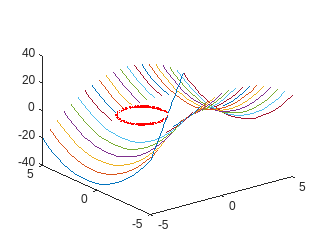

steps = 0.5;
x1 = -5:steps:5;
x2 = -5:steps:5;
[X1,X2] = meshgrid(x1,x2);

c = [-1 1];
r = sqrt(2);

viscircles(c,r);
hold on
plot(x1,x2);
hold off

The Feasible region is **closed and bounded** and the objective function is **continuous**

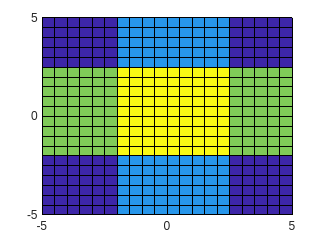

% conditions = 1 if first condition is active
conditions = (X1.^2 - 4 <= 0);

% conditions = 2 if second condition is active
% conditions = 3 if both conditions are hold
conditions = conditions + 2 * (X2.^2 - 4 <= 0);

surf(X1,X2, conditions);
view(2);

Calculation of the Hessian for the Objective Function

H = [-2 0
      0 2];
eigenvalue = eig(H);
display(eigenvalue);

eigenvalue =     -2
     2


- b) Is it convex problem? Why?

If the objective function is a **quadratic function**, then it needs a viscircles**positive semidefinite or positive definite** Hessian to be convex. 

A quadratic function is defined as $\frac{1}{2}x^T \textrm{Hx}+f^T x+r$

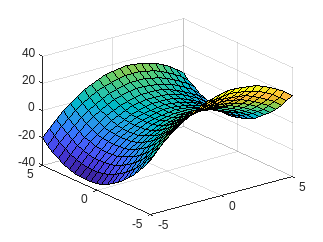

X3 = -X1.^2 + 2.*X1 + X2.^2 - 2.*X2;

surf(X1,X2,X3);
view(3);

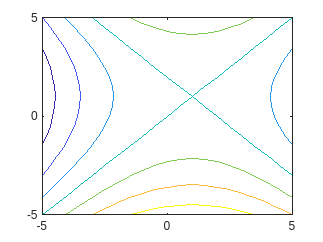


contour(X1,X2,X3);

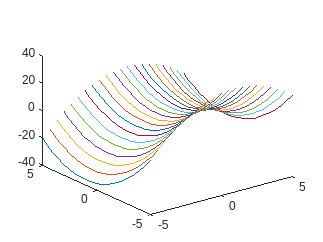

plot3(X1,X2,X3);

Graph with contraints

X3(conditions ~= 3) = NaN

X3 =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

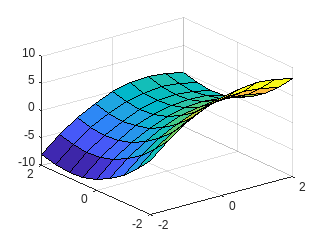


surf(X1,X2,X3);
view(3);

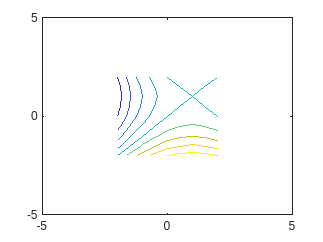


contour(X1,X2,X3);

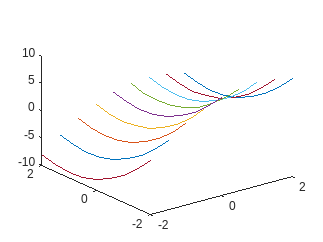

plot3(X1,X2,X3);

The Hessian is H. To check if it is **positive semidefinite**, we must compute the eigenvalues of H. If they are both positive, then it is **positive definite**. If one is positive and the other one is zero, then it is **positive semidefinite**. 

% Check Convexity
H = [-2 0
      0 2];

f = [2 
    -2];

eiganvalue = eig(H);
determinant = det(H);

- c) Does the Abadie constraints qualification hold in any feasible point? Why?

- If **all the constraint functions are linear**, then the Abadie constraints qualification holds at any feasible point.

- **Slater condition**: if the** g(x) **constraints are **convex**, the **h(x)** constraints are **linear** and there exists a point 𝑥̅ such that 𝑔(𝑥̅ ) < 0 (so, there exists an internal point in which the g(x) constraints are not active and the h(x) constraints are active), then the Abadie constraints qualification holds at any feasible point.

If all the gradients of the active constraints (a constraint function $g_i \left(\bar{x} \right)$ is active in $\bar{x}$ if $g_i \left(\bar{x} \right)=0$ and the h(x) constraints are always active) in each point of the feasible region are linear independent, then the Abadie constraints qualification holds at any feasible point. When we have combinations of linear and quadratic functions, this condition becomes a problem in the points in which multiple constraints are active.

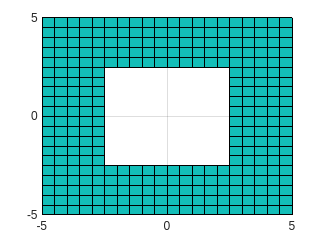

conditions = (X1.^2 - 4 <= 0)&(X2.^2 - 4 <= 0);
cond = zeros(length(X1));
cond(conditions) = NaN;

surf(X1,X2,cond);
view(2);

Representation 3D of Function + Contraints

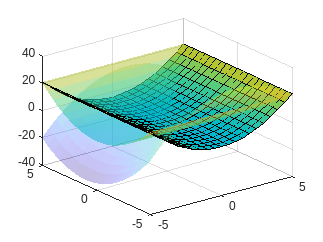

X4 = X1.^2 - 4;
X5 = X2.^2 - 4;

surf(X1,X2,X3, 'FaceAlpha',0.3, 'LineStyle','none');
hold on 
surf(X1,X2,X4);
surf(X1,X2,X5,'FaceAlpha', 0.5, 'EdgeColor','texturemap');
hold off

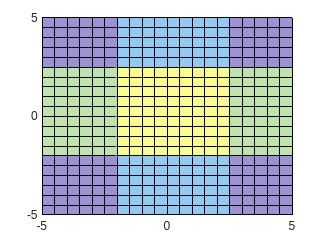

% cond = 1 where the constraint g1 is satisfied
cond = (X1.^2 - 4 <= 0);

% cond = 2 where constraint g2 is satisfied
% cond = 3 where both constraints are satisfied
cond = cond + 2 *(X2.^2 - 4 <= 0);

surf(X1, X2, cond, FaceAlpha=0.5);
view(2);

- d) Is the point (0, 0) a local minimum? Why?

X3(conditions ~= 3) = NaN

X3 =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 


surf(X1,X2,X3);
view(3);


contour(X1,X2,X3);

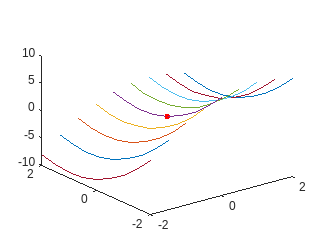

lambda =   -Inf
   NaN


plot3(X1,X2,X3);

hold on
plot3(0,0,0,'.r','markersize',10);
hold off

- e) Find all the solutions of the KKT system

We have to use the **Karush-Kahn-Tucker **system to find the minimum on point (0,0)


$$\nabla \textrm{KKT}=\nabla f\left(x^* \right)+\sum_{i=1}^m {\lambda_i }^* \nabla g_i \left(x^* \right)+\sum_{i=1}^p {\mu_i }^* \nabla h_i \left(x^* \right)$$



$$\left\lbrace \begin{array}{ll}
{\lambda_i }^* \nabla g_i \left(x^* \right) & =0\;\;\;\forall i=1,\ldotp \ldotp ,m\\
g\left(x^* \right) & \le 0\\
h\left(x^* \right) & =0
\end{array}\right.$$
 

As a result of KKT:


$$\left\lbrace \begin{array}{ll}
-2x_1 +2+{2\lambda }_1 x_1  & =0\\
2x_2 -2+{2\lambda }_2 x_2 \; & =0\\
x_1^2  & =4\\
x_2^2  & =4\\
\lambda_1 ,\lambda_2  & \ge 0
\end{array}\right.$$


Punto (0,0)

A = [1 -2  1  0  0
     2  2  3  0  0
     4  0  0 -1 -2
     0  2  0  1 -3
     0  0  8  1 -3];

b = [ 6
     12
      0  
      0  
      0];

f = zeros(length(b));

x = A\b;
display(x);

x =     6.0000
    0.0000
    0.0000
   14.4000
    4.8000
